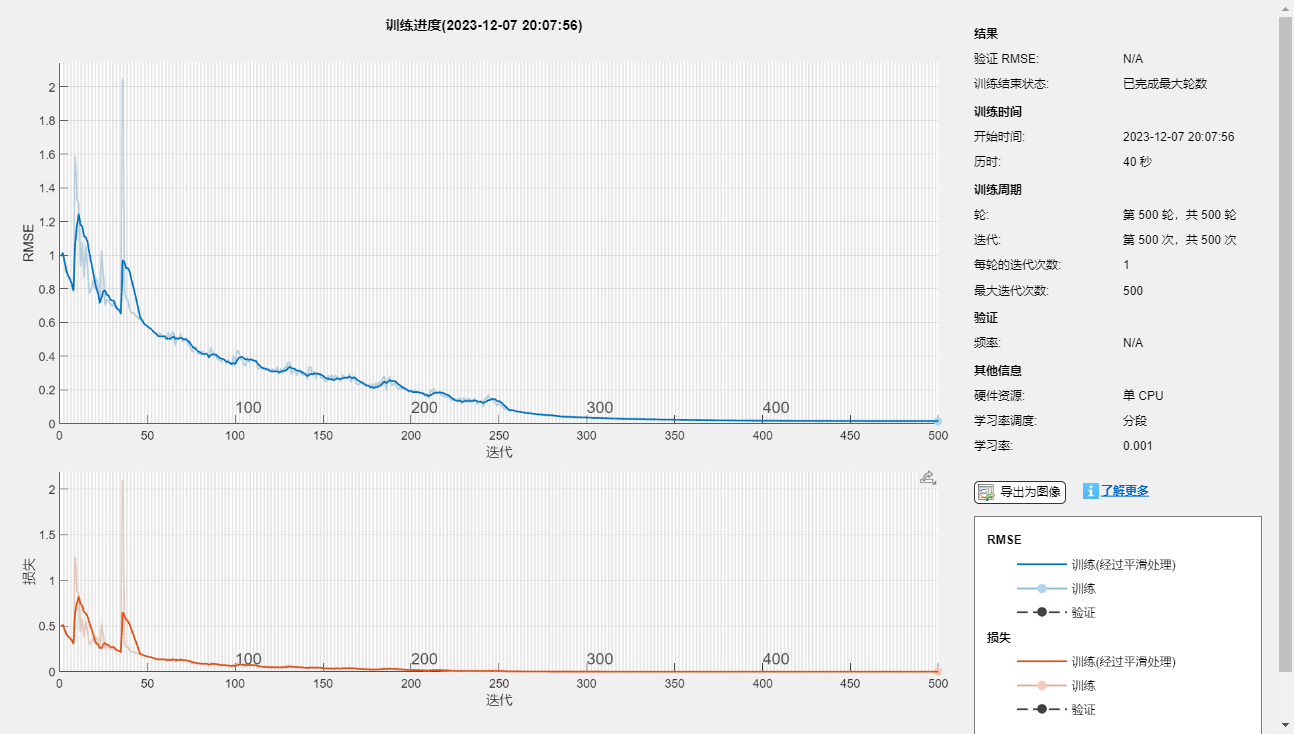

%机器学习时间序列预测
clc
clear
AA=xlsread('y.xls');
data=AA(:,1)';
%序列的前132 用于训练，后 12 用于测试
numTimeStepsTrain = floor(numel(data(1:107)));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);%就拟合预测值

%数据预处理
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
%输入LSTM的时间序列交替一个时间步
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
%%
%创建LSTM回归网络
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*3;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
%指定训练选项，求解器设置为adam， 250 轮训练。
%梯度阈值设置为 1。指定初始学习率 0.005，在 125 轮训练后通过乘以因子 0.2 来降低学习率。
options = trainingOptions('adam', ...
    'MaxEpochs',500, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',250, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
%训练LSTM
net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);
net = resetState(net);
net = predictAndUpdateState(net,XTrain);
 
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
%使用先前计算的参数对预测去标准化。
YPred = sig*YPred + mu;
%由于采用交叉步预测，前几个点往往不太精确，这里从第5个点开始
%计算评价指标
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 650.1632

mse=(mean((YPred-YTest).^2))

mse = 4.2271e+05

MAE=mean(abs(YPred-YTest))

MAE = 593.8038

MAPE=mean(abs((YPred-YTest)/YTest))

MAPE = 0.0222

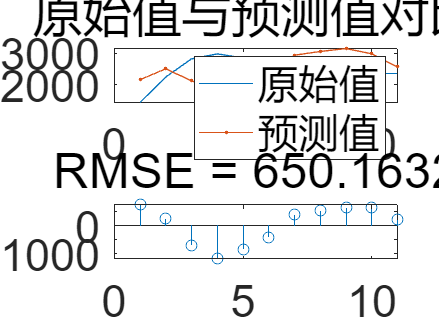

%将预测值与测试数据进行比较。
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["原始值" "预测值"])
ylabel("传染病例")
title("原始值与预测值对比")
set(gca,'fontsize',25);
subplot(2,1,2)
stem(YPred - YTest)
xlabel("天数")
ylabel("误差")
title("RMSE = " + rmse)
set(gca,'fontsize',25);

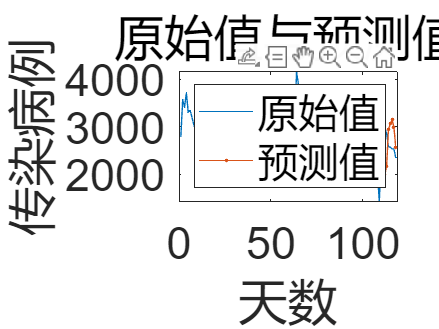

figure
%预测训练数据这张图没有用可注释掉
plot(data)
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
legend(["原始值" "预测值"])
ylabel("传染病例")
xlabel("天数")
title("原始值与预测值")
set(gca,'fontsize',25);
hold off